# Gaussian Mixture Models

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the data.

X = readmatrix("./data/X.xlsx", Sheet="X_3");
whos X

  Name        Size            Bytes  Class     Attributes

  X         154x2              2464  double              



## Tasks 1 & 4

You can use the `fitgmdist` function to fit a Gaussian mixture model to the data using *k* distributions.

`gmModel` `=` `fitgmdist``(``data``,``k``)``;`

You can specify the type of covariance matrix to use when fitting the distributions by setting the property `"CovarianceType"` in the function `fitgmdist`.

mdl = fitgmdist(X, 3, "CovarianceType", "diagonal");

## Task 2

The `cluster` function partitions the observations in `data` using `gmModel`.

`grps` `=` `cluster``(``gmModel``,``data``)``;`

grp = cluster(mdl, X);

## Task 3

You can visualize the groups by viewing the data in a scatter plot and assigning each group a different color.

`gscatter``(``X``(``:,``1``)``,``X``(``:,``2``)``,``grpNum``)`

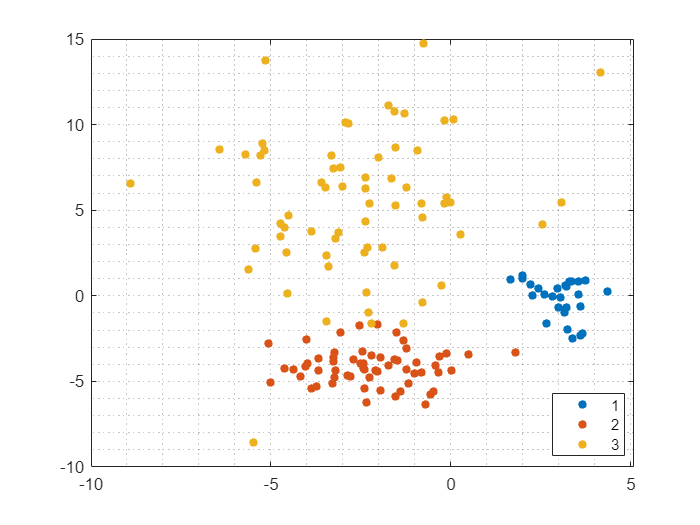

gscatter(X(:, 1), X(:, 2), grp)
grid minor